# Figure S5: Look into singular and negative values

% first, setup connctivity map
CurrentFolder = pwd

CurrentFolder = 'C:\Users\tiexu\OneDrive\文档\Researches\NYU-Vision\MFModel Code'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])

N_HC = 3; 
% Number of E and I neurons
n_E_HC = 54; n_I_HC = 31; % per side of HC
N_E = n_E_HC^2 * N_HC^2; % neuron numbers In all
N_I = n_I_HC^2 * N_HC^2;
% Grid sizes of E and I neurons; 
Size_HC = 0.500; % in mm;
Size_E = Size_HC/n_E_HC; Size_I = Size_HC/n_I_HC; 
% Projection: SD of distances
SD_E = 0.2/sqrt(2); SD_I = 0.125/sqrt(2);
Dist_LB = 0.36; % ignore the connection probability of dist>0.3mm
% Peak probability of projection
Peak_EE = 0.15; Peak_I = 0.6; 

% spatial indexes of E and I neurons
[NnE.X,NnE.Y] = V1Field_Generation(N_HC,1:N_E,'e');
[NnI.X,NnI.Y] = V1Field_Generation(N_HC,1:N_I,'i');

% determine connections between E, I
% sparse metrices containing 0 or 1. 
% Row_i Column_j means neuron j projects to neuron i
% add periodic boundary
C_EE = ConnectionMat(N_E,NnE,Size_E,...
                     N_E,NnE,Size_E,...
                     Peak_EE,SD_E,Dist_LB,1);

历时 19.115479 秒。



C_EI = ConnectionMat(N_E,NnE,Size_E,...
                     N_I,NnI,Size_I,...
                     Peak_I,SD_I,Dist_LB,0);

历时 8.434264 秒。



C_IE = ConnectionMat(N_I,NnI,Size_I,...
                     N_E,NnE,Size_E,...
                     Peak_I,SD_E,Dist_LB,0);

历时 8.354077 秒。



C_II = ConnectionMat(N_I,NnI,Size_I,...
                     N_I,NnI,Size_I,...
                     Peak_I,SD_I,Dist_LB,1);

历时 3.221045 秒。


## Variables and Parameters

%RefTimeE = zeros(N_E,1); VE = 0.5*rand(N_E,1)-0.5; SpE = sparse(N_E,1); GE_ampa_R = zeros(N_E,1); GE_nmda_R = zeros(N_E,1); GE_gaba_R = zeros(N_E,1); GE_ampa_D = zeros(N_E,1); GE_nmda_D = zeros(N_E,1); GE_gaba_D = zeros(N_E,1);
%RefTimeI = zeros(N_I,1); VI = 1.5*rand(N_I,1)-0.5; SpI = sparse(N_I,1); GI_ampa_R = zeros(N_I,1); GI_nmda_R = zeros(N_I,1); GI_gaba_R = zeros(N_I,1); GI_ampa_D = zeros(N_I,1); GI_nmda_D = zeros(N_I,1); GI_gaba_D = zeros(N_I,1); 
load('Initials.mat')
%parameters
S_EE = 0.024; S_II = 0.120; %S_IE = 0.0081; S_II = 0.048; %Tuned
%S_EE = 0.033; S_EI = 0.061; S_IE = 0.0087; S_II = 0.048;
%S_EE = 0.033; S_EI = 0.061; S_IE = 0.0087; S_II = 0.048;
%S_EE = 0.029; S_EI = 0.055; S_IE = 0.0081; S_II = 0.048; %Tuned
%S_EE = 0.028; S_EI = 0.056; S_IE = 0.0095; S_II = 0.042; % original
p_EEFail = 0.2; S_amb = 0.01;

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms
dt = 0.2;
gL_E = 1/20;  Ve = 14/3; S_Elgn = 2*S_EE; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; %S_Ilgn = 0.084; 
rhoI_ampa = 0.67;rhoI_nmda = 0.33;

lambda_E = 0.08; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.08; 
%rE_amb = 0.72; rI_amb = 0.36;
rE_amb = 0.50; rI_amb = 0.50;

%L6 input
S_IEOneTime = 0.20*S_II;
S_EL6 = 1/3*S_EE; S_IL6 = 1/3*S_IEOneTime;
rE_L6 = 0.25; % rI_L6 to be determined

% Replace S_EI by testing values
GridNum1 = 10;
GridNum2 = 10;
S_EI_Mtp = [0.8, 2.2]; % of S_EE
S_IE_Mtp = [0.1, 0.27]; % of S_II
S_EItest = linspace(S_EI_Mtp(1),S_EI_Mtp(2),GridNum1)*S_EE;
S_IEtest = linspace(S_IE_Mtp(1),S_IE_Mtp(2),GridNum2)*S_II;%*S_EE; I only specify a vecter length here
% Panel: Two proportions
PanelNum1 = 5;
PanelNum2 = 6;
S_Ilgn_Mtp = [1, 3]; % of S_Elgn
rI_L6_Mtp  = [1, 6]; % of rE_L6
S_Ilgntest = linspace(S_Ilgn_Mtp(1),S_Ilgn_Mtp(2),PanelNum1)*S_Elgn;
rI_L6test = linspace(rI_L6_Mtp(1),rI_L6_Mtp(2),PanelNum2)*rE_L6;

## Calculate input current

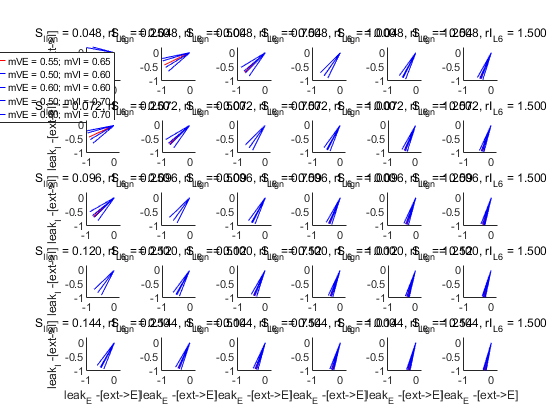

mVE = 0.5:0.05:0.6;
EInput = (Ve-mVE) * (lambda_E*S_Elgn + rE_amb*S_amb + rE_L6*S_EL6)*1000;
LeakE = gL_E*mVE*1000;
NegNetE = LeakE-EInput;

% all permutations
comb1 = repmat([1 3],1,2); comb2 = repmat([1 3],2,1);
combs = [comb1(:),comb2(:)];

figure('Name','net current input')
mVI = 0.6:0.05:0.7;
for S_IlgnInd = 1:PanelNum1
    S_Ilgn = S_Ilgntest(S_IlgnInd);
    for rI_L6Ind = 1:PanelNum2
        rI_L6 = rI_L6test(rI_L6Ind);
        IInput = (Ve-mVI) * (lambda_I*S_Ilgn + rI_amb*S_amb + rI_L6*S_IL6)*1000;
        LeakI = gL_I*mVI*1000;
        NegNetI = LeakI-IInput;
        % vectors
        MidVec = [NegNetE(2);NegNetI(2)];  
        BoundVecs = [NegNetE(combs(:,1));NegNetI(combs(:,2))];
        % normalize and plot      
        subplot(PanelNum1,PanelNum2,(S_IlgnInd-1)*PanelNum2+rI_L6Ind)
        hold on
        MidVec = MidVec/norm(MidVec);
        plot([0 MidVec(1)],[0 MidVec(2)],'r','DisplayName',sprintf('mVE = %.2f; mVI = %.2f',mVE(2),mVI(2)));
        for BoundInd = 1:size(BoundVecs,2)
            VecInd = combs(BoundInd,:);
            currentVec = BoundVecs(:,BoundInd);
            currentVec = currentVec/norm(currentVec);
            plot([0 currentVec(1)],[0 currentVec(2)],'b',...
                'DisplayName',sprintf('mVE = %.2f; mVI = %.2f',mVE(VecInd(1)),mVI(VecInd(2))));
        end
        hold off
        if S_IlgnInd == PanelNum1
           xlabel('leak_E -[ext->E]');
        end
        if rI_L6Ind == 1
            ylabel('leak_I -[ext->I]')
        end
         
        title(sprintf('S_{Ilgn} = %.3f, rI_{L6} = %.3f',S_Ilgn,rI_L6))
        axis([-1 0.2 -1 0.2])
        axis square
    end
end
subplot(PanelNum1,PanelNum2,1)
legend

## Calculate S matrix

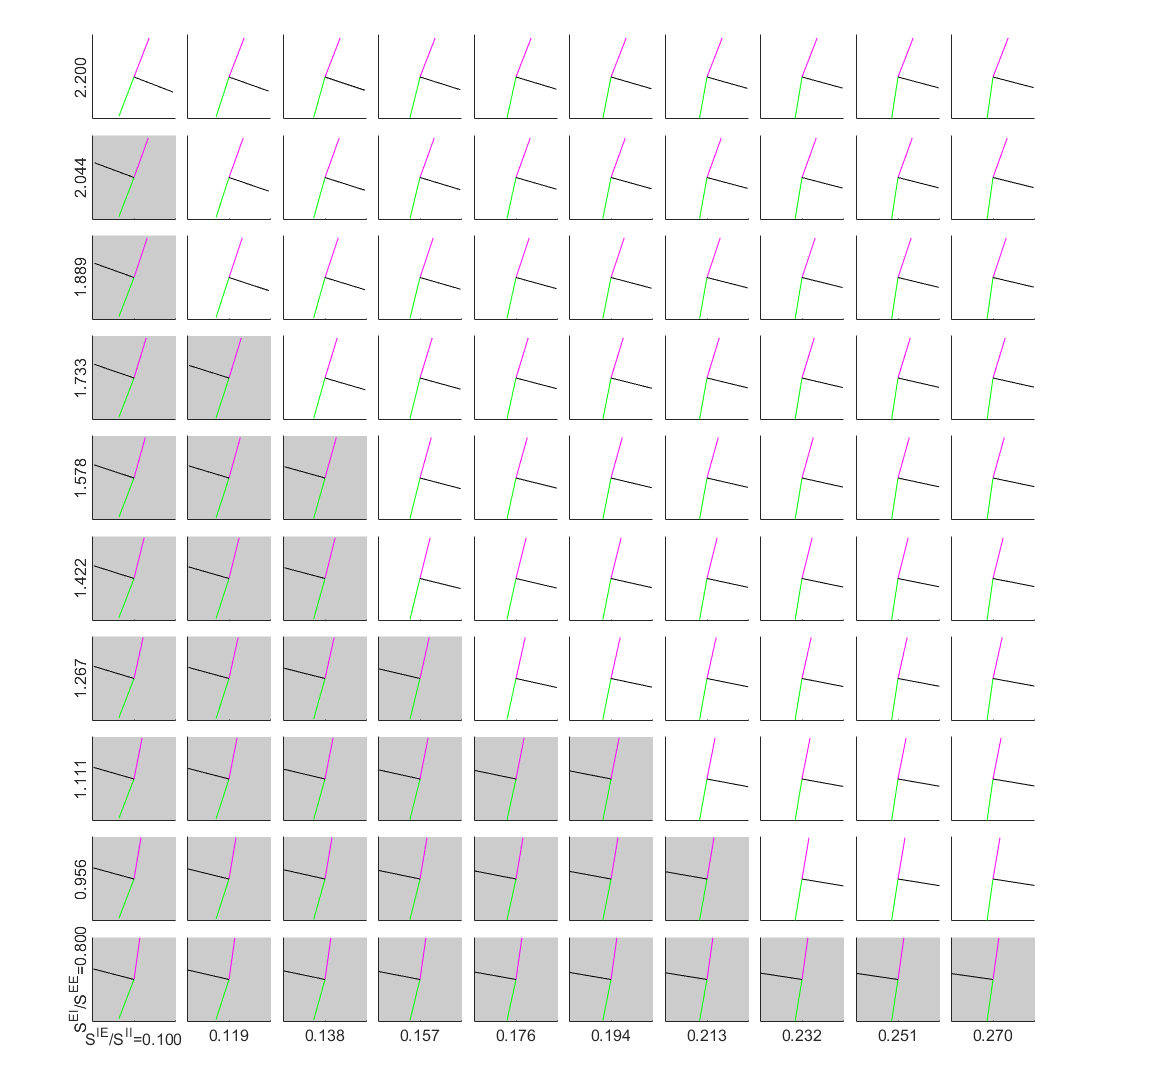

% Get connectivity for the center HC
E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
[E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);

I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
[I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

% Take averaged number of input neurons 
% NOTE! Only picking up the middle part
N_EE = mean(sum(C_EE(E_Ind,:),2)); N_EI = mean(sum(C_EI(E_Ind,:),2)); 
N_IE = mean(sum(C_IE(I_Ind,:),2)); N_II = mean(sum(C_II(I_Ind,:),2));

figure('Name','MF-dc:singular','units','normalized','outerposition',[0 0 0.6 1])
ha = tight_subplot(GridNum1,GridNum2,[.01 .01],[.05 .03],[.08 .10]);

mVE = 0.55; mVI = 0.65;
for S_EIInd = 1:GridNum1
    S_EI = S_EItest(S_EIInd);
    for S_IEInd = 1:GridNum2
        S_IE = S_IEtest(S_IEInd);
        MatEI = [N_EE*S_EE*(Ve-mVE)*(1-p_EEFail), N_EI*S_EI*(Vi-mVE);
                 N_IE*S_IE*(Ve-mVI),              N_II*S_II*(Vi-mVI)];
        A =  eye(2) - MatEI;
        a1 = A*[1;0]; a1 = a1/norm(a1);
        a2 = A*[0;1]; a2 = a2/norm(a2);
        a_mid = a1+a2; a_mid = a_mid/norm(a_mid);
        
        %subplot(GridNum1,GridNum2,(GridNum1-S_EIInd)*GridNum2+S_IEInd)
        axes(ha((GridNum1-S_EIInd)*GridNum2+S_IEInd));
        ax1a = gca;
        hold on
        plot([0 a1(1)], [0 a1(2)], 'g', 'DisplayName','\alpha_1');
        plot([0 a2(1)], [0 a2(2)], 'm', 'DisplayName','\alpha_2');
        plot([0 a_mid(1)], [0 a_mid(2)], 'k', 'DisplayName','\alpha_{mid}');
        hold off
%         if S_EIInd == GridNum1
%            xlabel('leak_E -[ext->E]');
%         end
%         if S_IEInd == 1
%             ylabel('leak_I -[ext->I]')
%         end
        axis([-1 1 -1 1])
        axis square  
        set(gca,'yticklabel','')
        set(gca,'xticklabel','')
        
        % set ticks, labels, titles, etc.
        if S_IEInd == 1 && S_EIInd >1
           h =  ylabel(sprintf('%.3f',S_EI/S_EE)) ;
           set(h, 'FontSize', 12) 
        end
        
        
        if S_EIInd == 1 && S_IEInd >1
            h =  xlabel(sprintf('%.3f',S_IE/S_II));     
            set(h, 'FontSize', 12) 
        end
        
        if S_EIInd == 1 && S_IEInd == 1
            h =  ylabel(sprintf('S^{EI}/S^{EE}=%.3f',S_EI/S_EE)) ;
           set(h, 'FontSize', 12) 
            h =  xlabel(sprintf('S^{IE}/S^{II}=%.3f',S_IE/S_II));     
            set(h, 'FontSize', 12)
        end
        
        if det([a1,a2])<=0
        set(gca,'Color',[0.8,0.8,0.8])
        end
    end
end

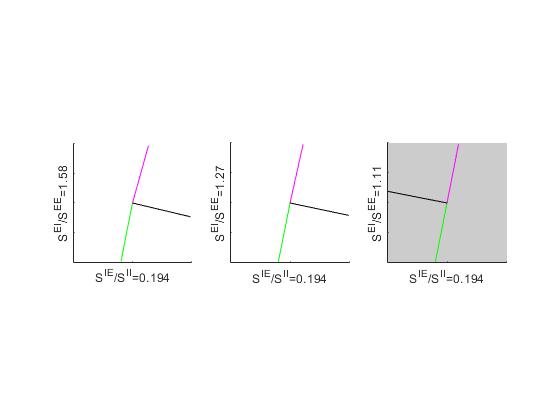

% subplot(GridNum1,GridNum2,1)
% legend

figure('Name','MF-dc:singular one col')
S_IEInd = 6;
S_EIInd = [6,4,3];
for Ind = 1:3
    S_EI = S_EItest(S_EIInd(Ind));
    S_IE = S_IEtest(S_IEInd);
        MatEI = [N_EE*S_EE*(Ve-mVE)*(1-p_EEFail), N_EI*S_EI*(Vi-mVE);
                 N_IE*S_IE*(Ve-mVI),              N_II*S_II*(Vi-mVI)];
        A =  eye(2) - MatEI;
        a1 = A*[1;0]; a1 = a1/norm(a1);
        a2 = A*[0;1]; a2 = a2/norm(a2);
        a_mid = a1+a2; a_mid = a_mid/norm(a_mid);
        
        %subplot(GridNum1,GridNum2,(GridNum1-S_EIInd)*GridNum2+S_IEInd)
        subplot(1,3,Ind)
        ax1a = gca;
        hold on
        plot([0 a1(1)], [0 a1(2)], 'g', 'DisplayName','\alpha_1');
        plot([0 a2(1)], [0 a2(2)], 'm', 'DisplayName','\alpha_2');
        plot([0 a_mid(1)], [0 a_mid(2)], 'k', 'DisplayName','\alpha_{mid}');
        hold off
%         if S_EIInd == GridNum1
%            xlabel('leak_E -[ext->E]');
%         end
%         if S_IEInd == 1
%             ylabel('leak_I -[ext->I]')
%         end
        axis([-1 1 -1 1])
        axis square  
        set(gca,'yticklabel','')
        set(gca,'xticklabel','')
        ylabel(sprintf('S^{EI}/S^{EE}=%.2f',S_EI/S_EE))
        xlabel(sprintf('S^{IE}/S^{II}=%.3f',S_IE/S_II)); 
                if det([a1,a2])<=0
        set(gca,'Color',[0.8,0.8,0.8])
        end
end